# Color Clustering

Goal: cluster the color of an image 

[https://www.mathworks.com/help/images/color-based-segmentation-using-k-means-clustering.html](https://www.mathworks.com/help/images/color-based-segmentation-using-k-means-clustering.html)

Method: k-means clustering

clear all;
close all;

## 0) Import the data

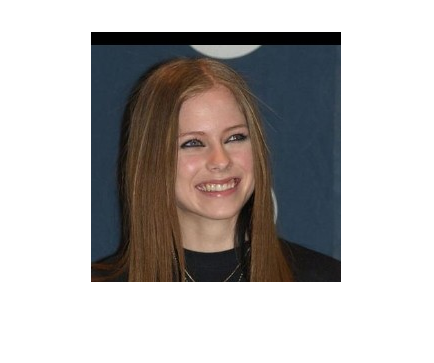

% import the data
im_rgb = im2double(imread('../lfw/Avril_Lavigne_0001.jpg'));
imshow(im_rgb)

## k-Means clustering

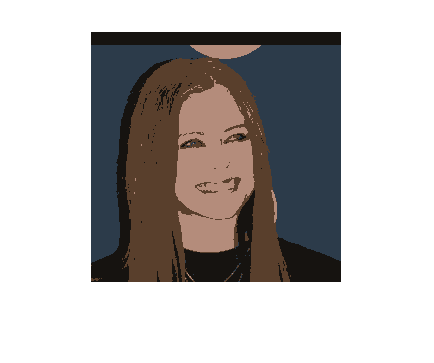

% hyperparameters
n_cluster = 4; % number of output colors
gamma = 0.5; % color adjustement
isLAB = false; % space in which to perform the clustering

% check in which space the clusterign should be performed
if isLAB
    im = rgb2lab(im_rgb);
else
    im = im_rgb;
end

% apply k-means clustering
im_flat = reshape(im, [], 3);
[idx, clusters] = kmeans(im_flat, n_cluster);

idx = repmat(reshape(idx, size(im, 1), size(im, 2)), 1, 1, 3);

% color the pixels with the cluster colors
im_cluster = zeros(size(im));
for k=1 : size(clusters, 1)
    c = reshape(clusters(k,:), 1, 1, 3);
    im_cluster = im_cluster +  (idx == k) .* c;
end

% get back to the RGB space
if isLAB
    im_cluster = lab2rgb(im_cluster);
end
imshow(im_cluster)

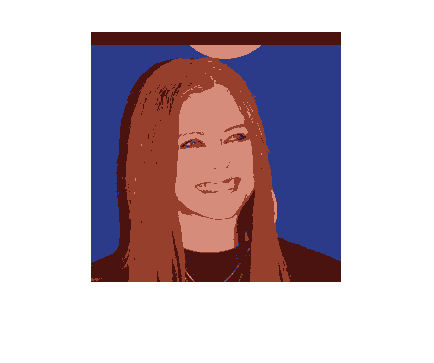


% identify the most important channel for each pixel
max_channel = max(im_cluster, [], 3);

% adjust the colors
im_color = (im_cluster == max_channel) .* im_cluster.^gamma + (im_cluster ~= max_channel) .* im_cluster;
imshow(im_color)

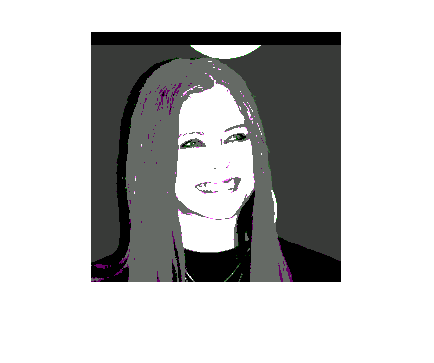

% compare the result from clustering in the rgb vs the lab space
im_color_rgb = cluster_color(im_rgb, n_cluster, gamma, false);
im_color_lab = cluster_color(im_rgb, n_cluster, gamma, true);

imshowpair(im_color_rgb, im_color_lab, '')

## Unsuccessful experiments

Unavailable function in Matlab < R2018b

% tune_img_lab = rgb2lab(tune_img);
% ab = tune_img_lab(:,:,2:3);
% ab = im2single(ab);
% nColors = 3;
% 
% % repeat the clustering 3 times to avoid local minima
% pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);